## Entropy-Based Voice Detection: Static Threshold

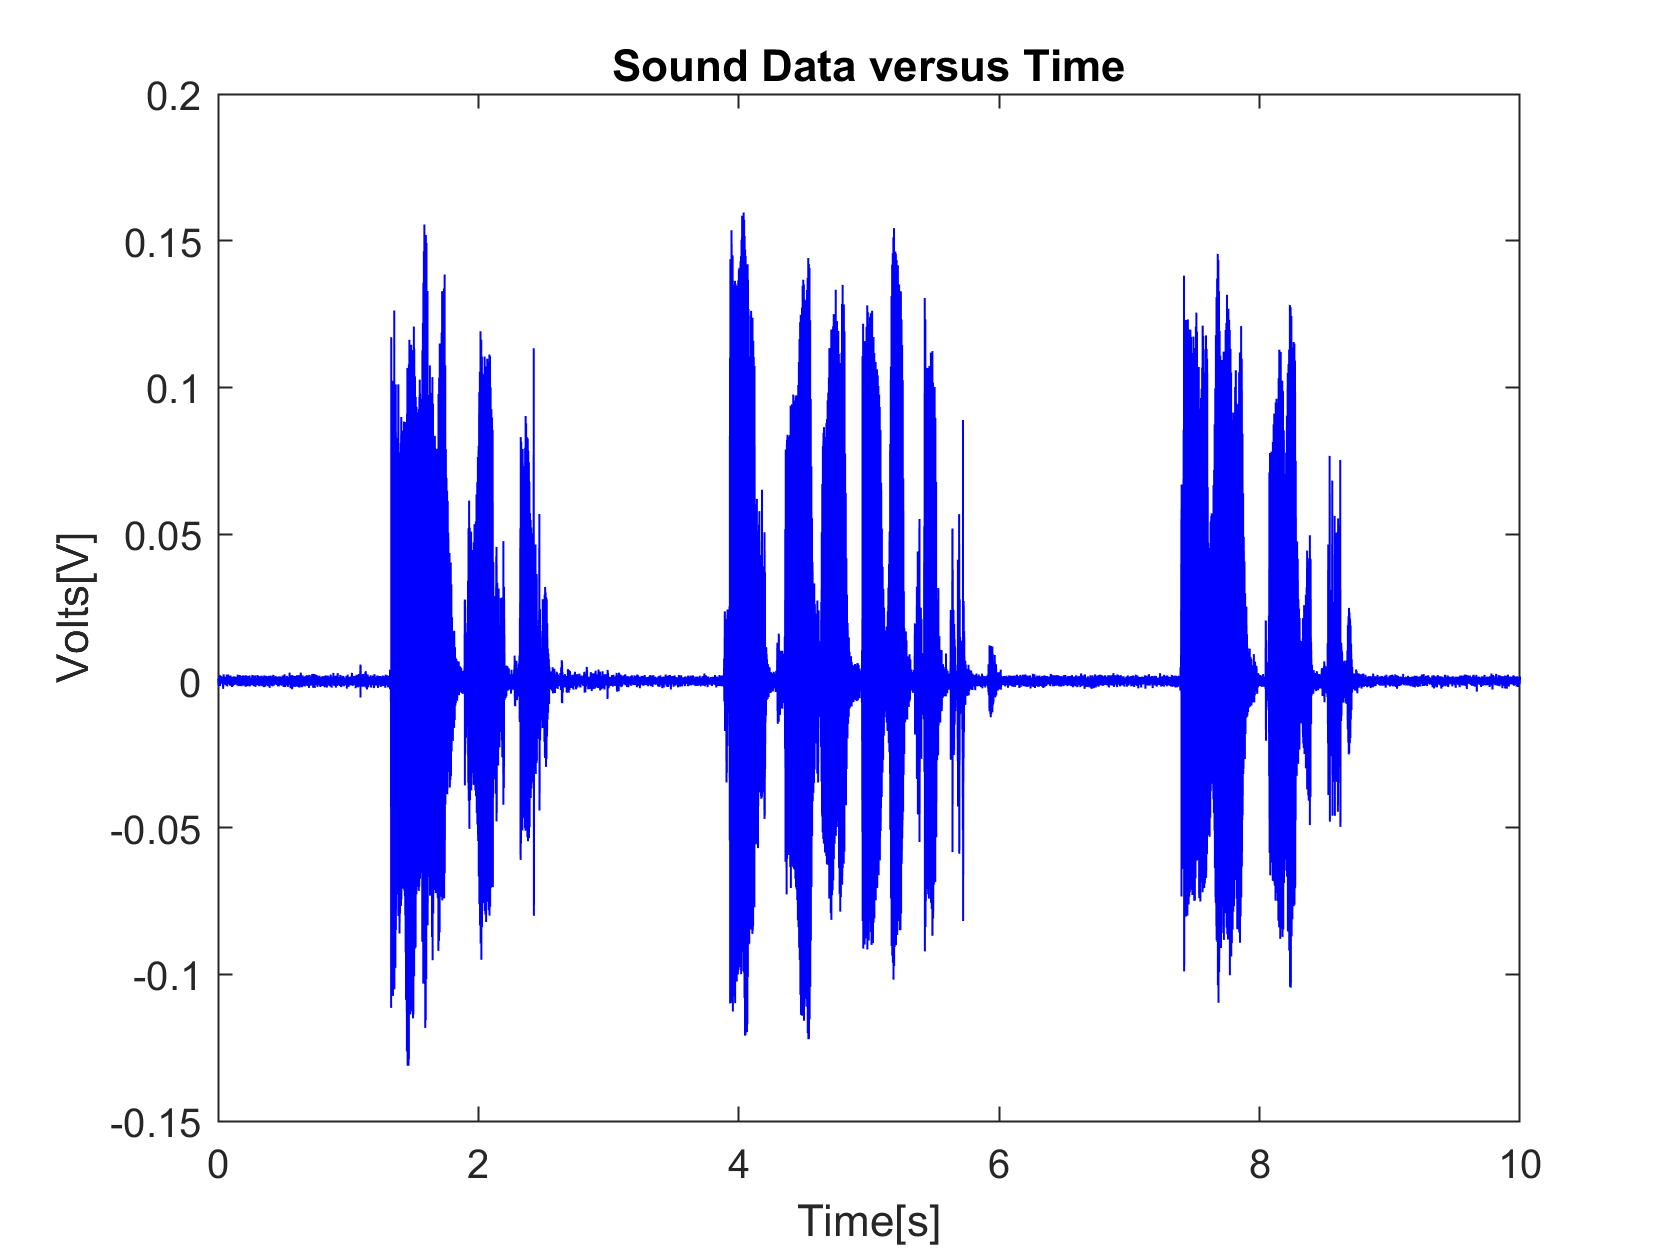

clear;
%read in sound data
[d,s]= audioread('C:\DSP Project\clean_ness_speech.wav');
%cut to 10s
t = 1/s*(0:length(d)-1);
for i =1:1:length(t)-1
    if t(i)==10
        cut=i;
    end
end 
fs=s;
t = t(1:cut);
d = d(1:cut);
%for adding babble noise
% d = d(1:cut);
% [d1, s1] = audioread('C:\DSP Project\babble.wav');
% d1 = interp(d1, 6);
% d1 = 0.1*d1;
% l=length(d1);
% d1(l+1)=0;
% n=d1+d';
% d=n;

%for adding car noise
[d1, s1] = audioread('C:\DSP Project\car.wav');
d1 = interp(d1, 6);
d1 = 0.1*d1;
l=length(d1);
d1(l+1)=0;
n=d1+d';
d=n;


%for white noisy signals
% d = d(1:cut);
% SNR=0; %set SNR
% z=awgn(d,SNR,'measured');
% figure();
% plot(z);
% d=z;

figure();
plot(t,d, 'b'); xlabel("Time[s]"); ylabel("Volts[V]"); title("Sound Data versus Time");

## Find Entropy of Each Frame

%find entropy
%each frame is 10ms long
frame_length = 0.01;
n_frames = 10/frame_length;
sample_per_frame =s*frame_length;
last_samp = 1;

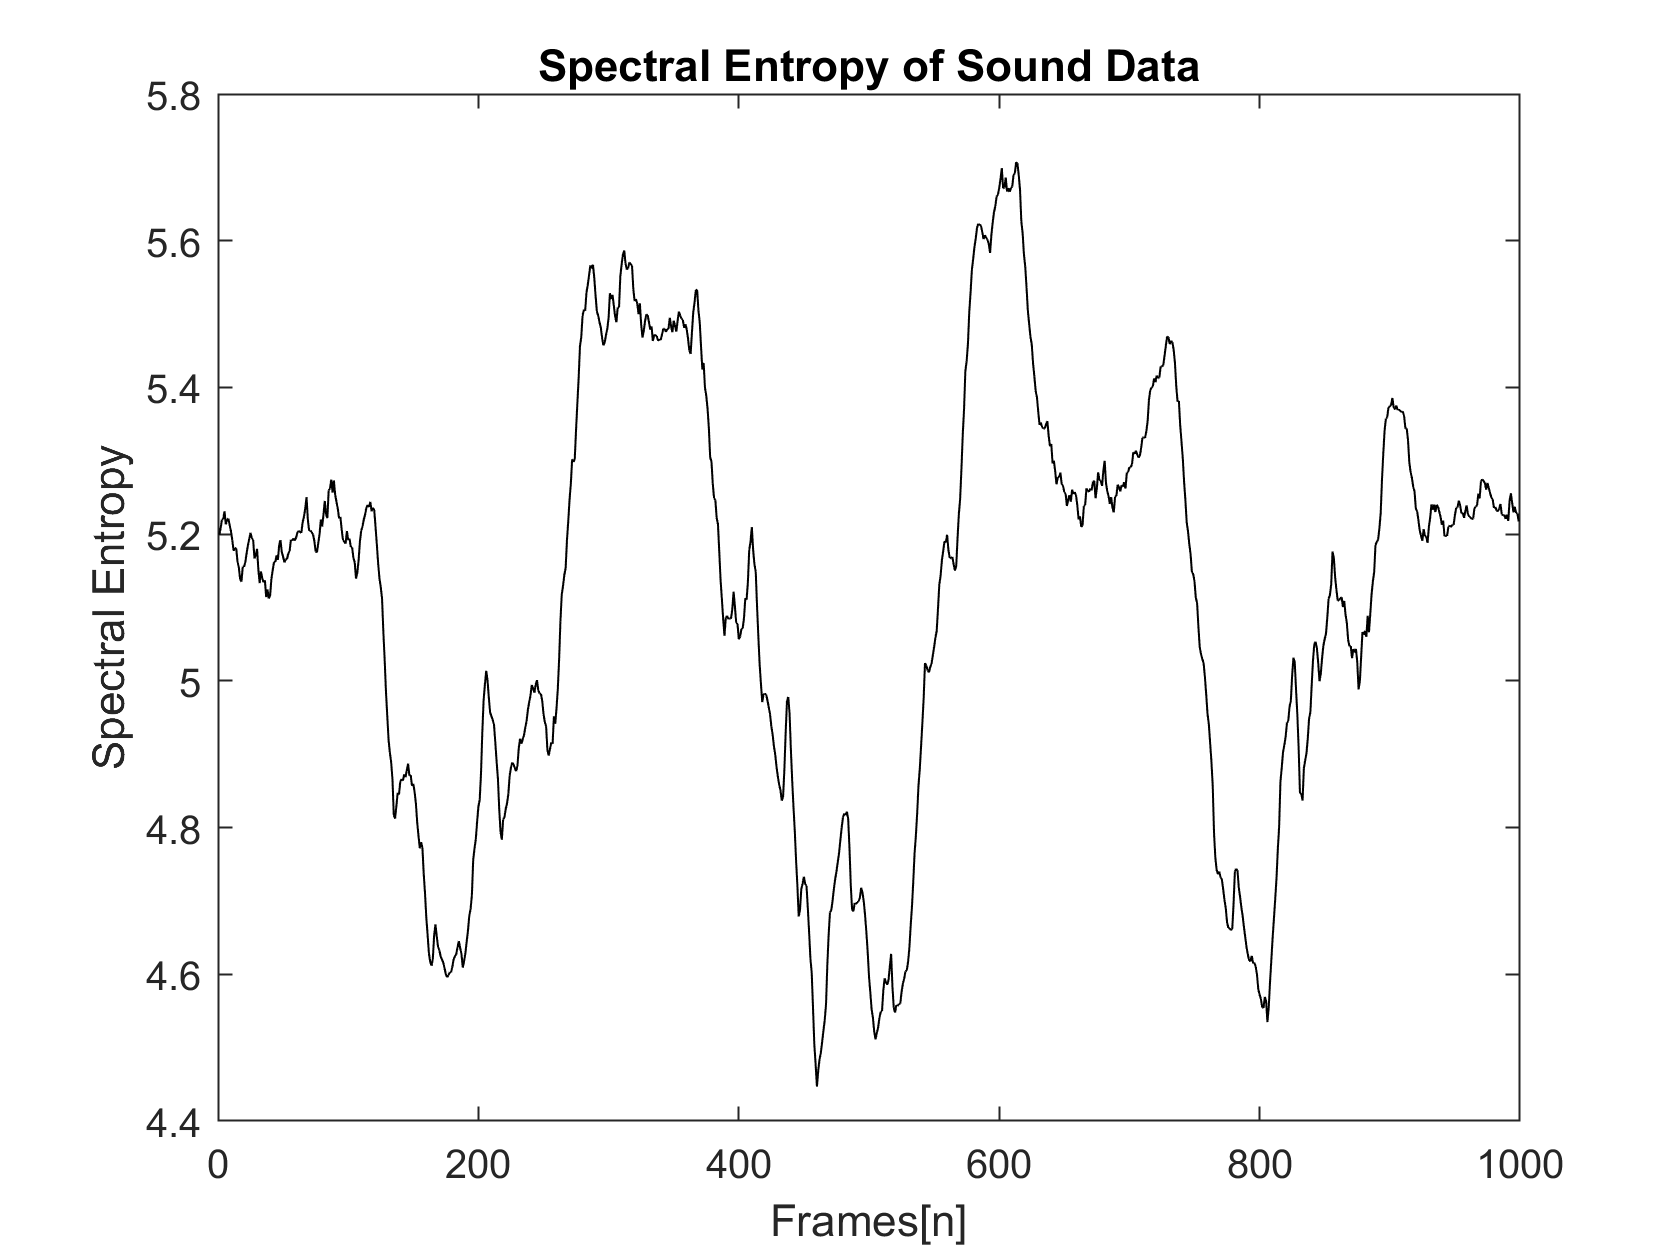

%divide sampled data into frames- every column of new_d is one frame
for k=1:1:n_frames
   new_d(:,k)= d(last_samp:last_samp+sample_per_frame) ;
   last_samp = last_samp + sample_per_frame;
end
new_d(sample_per_frame+1,:)=[];
new_d(:,1)=[]; %where every column is 1 frame (10ms long)

%FFT example
% x = new_d(:,1);
% NFFT=2^11; %NFFT-point DFT      
% X=fft(x,NFFT); %compute DFT using FFT        
% nVals=0:NFFT-1; %DFT Sample points       
% plot(nVals,abs(X));      
% title('Double Sided FFT - without FFTShift');        
% xlabel('Sample points (N-point DFT)')        
% ylabel('DFT Values');

NFFT=2^11; %need to take an NFFT-point DFT (NFFT is the next power of 2 after the sampling frequency)
%find FFT of each frame
for i = 1:1:999
    x = new_d(:,i);
    X=fftshift(fft(x,NFFT));
    fVals=fs*(-NFFT/2:NFFT/2-1)/NFFT;
    X = X((NFFT/2)+1:end);
    fVals = fVals((NFFT/2)+1:end);
    %find spectral energy of each frequency component in each frame
    E(:,i) = abs(X.*conj(X));
    %uncomment below if want to show plot of FFT
%     figure()
%     plot(fVals((NFFT/2)+1:end),abs(X((NFFT/2)+1:end)),'b');
%     title('Double Sided FFT - with FFTShift');
%     xlabel('Frequency (Hz)')
%     ylabel('|DFT Values|');
end

% find spectral entropy of each frame
for i = 1:1:999
sum_E = sum(abs(E(:,i)));
pi = abs(E(:,i))./sum_E;
term = pi.*log2(pi);
H(i) = -sum(term);
end

%smooth entropy using moving average filter
H = movmean(H, 50);
plot(H,'k'); xlabel("Frames[n]"); ylabel("Spectral Entropy"); title("Spectral Entropy of Sound Data");

## Classify Frames as Speech and Noise

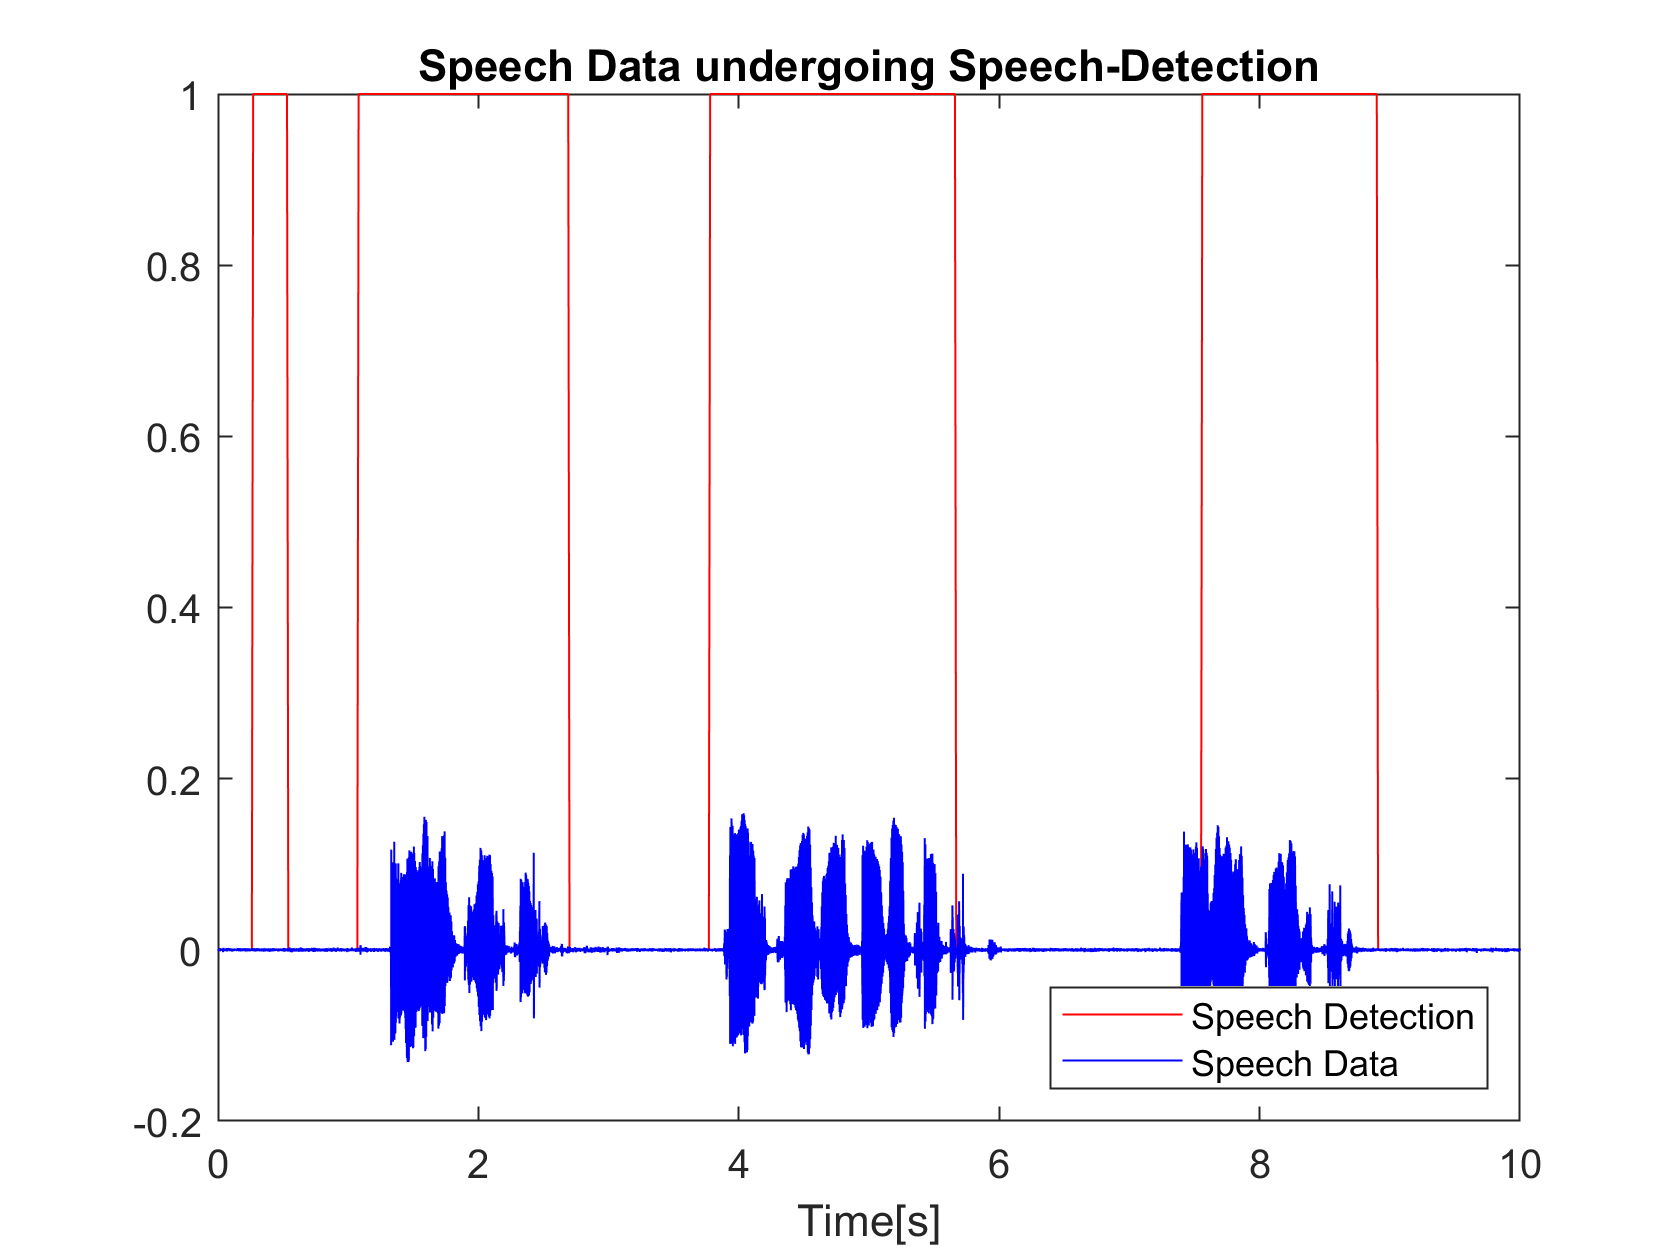

%find threshold
%assume first 27 frames as purely noise- take these as noise threshold
% if any frame's entropy is less than threshold- classify as speech
init_t = mean(H(1:27));
sorted(1:27) = 0;
for i =1:1:(999/27 -1)
    check = H(i*27+1:(i+1)*27);
    check= mean(check);
    if check<init_t
        sorted(i*27+1:(i+1)*27) = 1;
    else
        sorted(i*27+1:(i+1)*27) = 0;
    end
end
sorted_time(1)=0;
for i = 1:1:length(sorted)-1
    sorted_time(i+1)= 0.01*i;
end
figure();
plot(sorted_time, sorted,'r'); hold on; plot(t, d, 'b'); xlabel("Time[s]"); title("Speech Data undergoing Speech-Detection");
legend("Speech Detection", "Speech Data", "Location", "southeast");

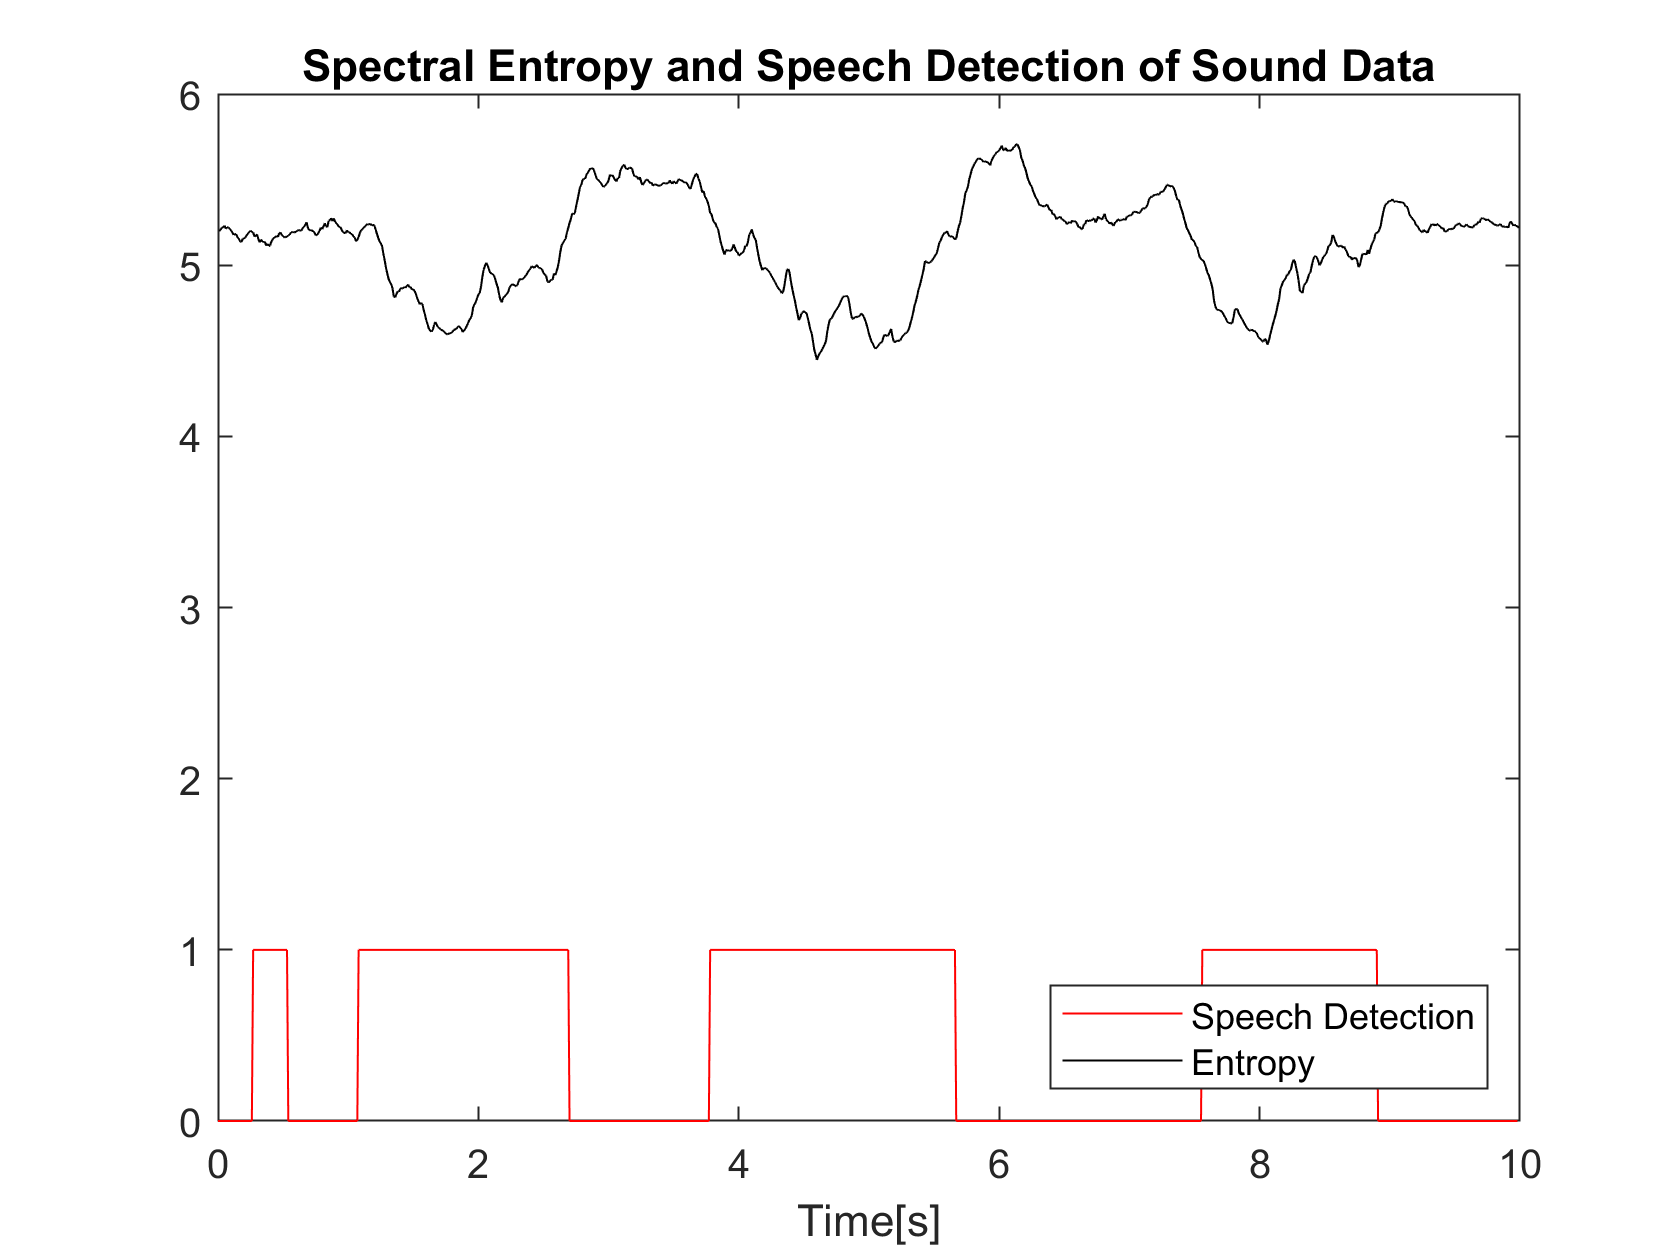

figure();
for i=1:1:length(H);
    time_H(i) = i*0.01;
end
plot(sorted_time, sorted, "Color", 'r'); hold on; plot(time_H, H, 'k'); xlabel("Time[s]"); legend("Speech Detection", "Entropy", "Location", "southeast"); title("Spectral Entropy and Speech Detection of Sound Data")

## Find % accuracy

%use for white noise, babble noise and car noise
VAD_labelled(1:128) =0;
VAD_labelled(129:260)=1;
VAD_labelled(261:380) = 0;
VAD_labelled(381:603) = 1;
VAD_labelled(604:736) = 0;
VAD_labelled(737:893) = 1;
VAD_labelled(893:999) = 0;

%use for office noise
% VAD_labelled2(1:181) = 0;
% VAD_labelled2(182:421) = 1;
% VAD_labelled2(422:476) = 0;
% VAD_labelled2(477:699) = 1;
% VAD_labelled2(700:709) = 0;
% VAD_labelled2(710:776) = 1;
% VAD_labelled2(777:825) = 0;
% VAD_labelled2(826:982) = 1;
% VAD_labelled2(983:999) = 0;

num_correct=0;
for i=1:1:999
    if sorted(i)==VAD_labelled(i)
        num_correct=num_correct+1;
    end
end
num_correct

num_correct = 883

pc_correct = num_correct/999 * 100

pc_correct = 88.3884

## Make Verification Audio Clip

% l =0;
% for i = 1:1:length(VAD_labelled)
%     if sorted(i) == 0
%         a(l+1:i*sample_per_frame) = 0;
%     else 
%         a(l+1:i*sample_per_frame) = 1;
%     end
%     l = length(a);
% end
% d_actual = d(sample_per_frame+2:end);
% new_a = d_actual.* a';
% figure();
% audiowrite('female_babble_static_entropy.wav', new_a, s);
% [y, Fs] = audioread('female_babble_static_entropy.wav');
% sound(y, Fs);
